# Interactive MATLAB Lab 1.10: Boundary-Value Problem Explorer

In a Live Script, turn "caseType" into a drop-down control.

caseType = "Unique";   % Options: "Unique", "Infinite", "None"

syms x c1 c2
generalSolution = c1*cos(x) + c2*sin(x);

disp("Differential equation: y'' + y = 0")

Differential equation: y'' + y = 0


disp("General solution:")

General solution:


disp(generalSolution)

$$c_{1}\,\cos\left(x\right)+c_{2}\,\sin\left(x\right)$$

Boundary conditions: y(0)=0, y(pi/2)=1


Solution:


$$\sin\left(x\right)$$

Exactly One Solution


Both constants are uniquely determined.


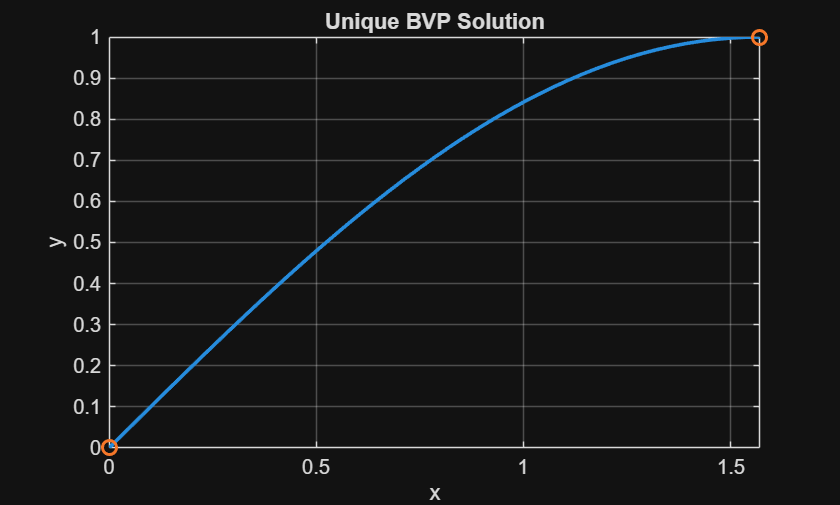


switch caseType
    case "Unique"
        conditions = [ ...
            subs(generalSolution,x,0) == 0, ...
            subs(generalSolution,x,pi/2) == 1 ...
        ];

        constants = solve(conditions,[c1 c2]);
        solution = simplify(subs(generalSolution, ...
            [c1 c2],[constants.c1 constants.c2]));

        outcome = "Exactly One Solution";
        explanation = "Both constants are uniquely determined.";

        disp("Boundary conditions: y(0)=0, y(pi/2)=1")
        disp("Solution:")
        disp(solution)
        disp(outcome)
        disp(explanation)

        figure
        fplot(solution,[0 pi/2],'LineWidth',1.8)
        hold on
        plot([0 pi/2],[0 1],'o','MarkerSize',7,'LineWidth',1.5)
        hold off
        grid on
        xlabel('x')
        ylabel('y')
        title('Unique BVP Solution')

    case "Infinite"
        outcome = "Infinitely Many Solutions";
        explanation = "The condition y(0)=0 forces c1=0, while y(pi)=0 leaves c2 arbitrary.";

        disp("Boundary conditions: y(0)=0, y(pi)=0")
        disp("Conditions on constants: c1=0, c2 arbitrary")
        disp(outcome)
        disp(explanation)

        figure
        hold on
        amplitudes = [-2 -1 1 2];
        for k = 1:numel(amplitudes)
            A = amplitudes(k);
            fplot(@(x) A*sin(x),[0 pi],'LineWidth',1.4)
        end
        hold off
        grid on
        xlabel('x')
        ylabel('y')
        title('Several Members of the Infinite Solution Family')

    case "None"
        outcome = "No Solution";
        explanation = "The condition y(0)=0 forces c1=0, but then y(pi)=0 for every c2, so y(pi)=1 is impossible.";

        disp("Boundary conditions: y(0)=0, y(pi)=1")
        disp(outcome)
        disp(explanation)

        figure
        axis off
        text(0.5,0.5, ...
            'No solution satisfies both boundary conditions.', ...
            'HorizontalAlignment','center', ...
            'FontSize',14, ...
            'FontWeight','bold')
end